# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

% modelo de orden 6
% model_6 = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06)
model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)


model_6 =
 
                                   1
  --------------------------------------------------------------------
  1e-06 s^6 + 6e-05 s^5 + 0.0015 s^4 + 0.02 s^3 + 0.15 s^2 + 0.6 s + 1
 
Continuous-time transfer function.
Model Properties



[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
Ts = round(1/(5*high_freq_pole), 3)

Ts = 0.0200


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  7.491e-08 z^5 + 3.6e-06 z^4 + 1.608e-05 z^3 + 1.354e-05 z^2 + 2.152e-06 z + 3.179e-08
  -------------------------------------------------------------------------------------
          z^6 - 4.912 z^5 + 10.05 z^4 - 10.98 z^3 + 6.74 z^2 - 2.207 z + 0.3012
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model

[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se verifican los modelos continuos y discretos comparando sus respuestas al escalón

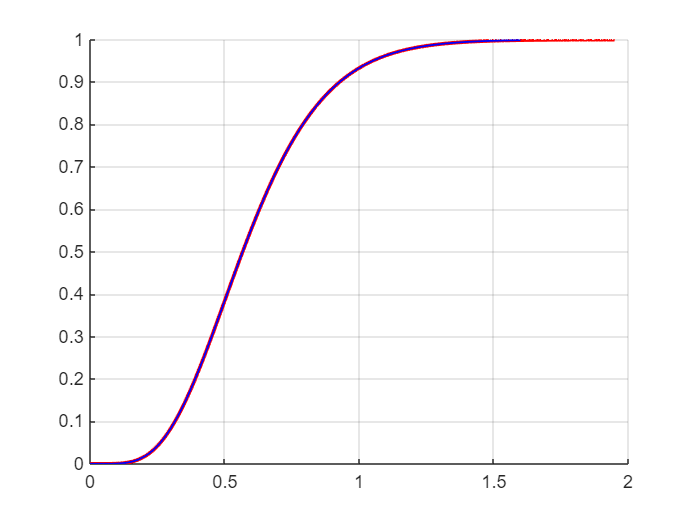

[cont_y, cont_t] = step(model_6);
[disc_y, disc_t] = step(model_discrete);

figure; hold on; grid on;
plot(cont_t, cont_y, 'r', 'LineWidth', 2);
plot(disc_t, disc_y, 'b', 'LineWidth', 1);

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7
   x1    4.912   -10.05    10.98    -6.74    2.207  -0.3012        1
   x2        1        0        0        0        0        0        0
   x3        0        1        0        0        0        0        0
   x4        0        0        1        0        0        0        0
   x5        0        0        0        1        0        0        0
   x6        0        0        0        0        1        0        0
   x7        0        0        0        0        0        0        1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  7.491e-08    3.6e-06  1.608e-05  1.354e-05  2.152e-06  3.179e-08          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.


Se cargan las matrices F y $\phi \;$

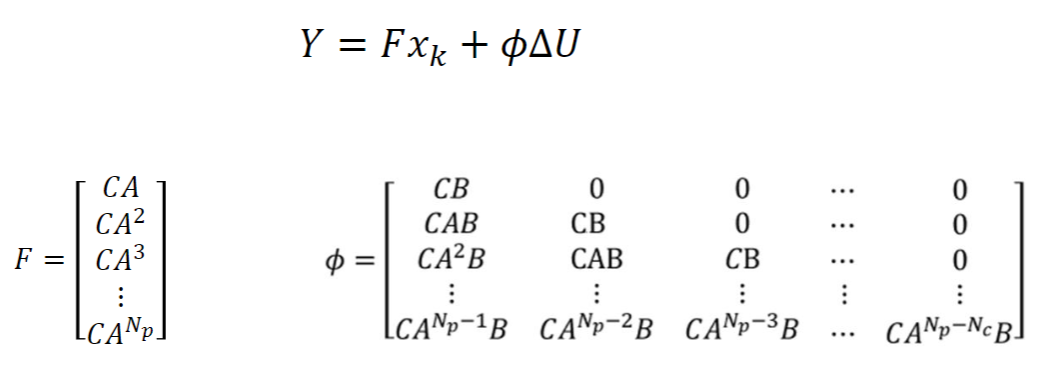

## Para calcular Np consideré que si Ts=0.1 y Tr=1.4 entonces entran 14 muestras hasta que se extinguen los transitorios

# IMPORTANTE: No se si lo anterior es cierto

% Np = round(1.4/Ts);
% Nc = 3;

% Esto genera F para un rango dinámico Np
% F_mat = zeros(Np, length(A_expanded));
% F_mat(1, :) = C_expanded*A_expanded;
% for i = 2:Np
%     F_mat(i, :) = F_mat(i-1, :)*A_expanded;
% end
% F_mat
% 
% % Esto genera phi para un rango dinámico de Np y Nc
% phi_mat = zeros(Np, Nc);
% for j = 1:Nc
%     for i = 1:Np
%         if (i < j)
%             phi_mat(i, j) = 0;
%         elseif (i == j)
%             phi_mat(i, j) = C_expanded*B_expanded;
%         else
%             phi_mat(i, j) = C_expanded*(A_expanded^(Np-j))*B_expanded;
%         end
%     end
% end
% phi_mat

% reference = 1;
% [Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

A continuación se calculan las entradas $\Delta U$de manera analítica

% states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% Rs = ones(1, Np);
% dU = ((((phi_mat')*phi_mat+ref_weight_mat)^(-1))*(phi_mat'))*(Rs*reference-F_mat*states)

% Rs*reference
% F_mat*states
% (Rs*reference-F_mat*states)

states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states)

Ahora se hace una simulación de la acción de control en diferencias

Np = round(1.4/Ts)

Np = 70

Nc = 3;
reference = 1;
rw = 0.1;
ref_weight_mat = rw*eye(Nc);
[Phi, Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

BarRs =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



% writeMatrixToHeader(Phi_Phi, 'phi_phi.h', 'phi_phi');
% writeMatrixToHeader(Phi_F, 'phi_f.h', 'phi_f');
% writeMatrixToHeader(Phi_R, 'phi_r.h', 'phi_r');
% writeMatrixToHeader(A_e, 'Ae.h', 'Ae');
% writeMatrixToHeader(B_e, 'Be.h', 'Be');
% writeMatrixToHeader(C_e, 'Ce.h', 'Ce');

% Estas son las matrices que voy a cargar al uC
% No estoy seguro de si se calculan así
firstOneAndZeros = zeros(1, length(Phi_Phi));
firstOneAndZeros(1) = 1;

Phi_Phi_R_INV = ((Phi_Phi+ ref_weight_mat)^(-1));
Ky = firstOneAndZeros * (Phi_Phi_R_INV  * ((Phi')*ones(length(Phi), 1)))

Ky = 3.3889

Kmpc = firstOneAndZeros * (Phi_Phi_R_INV  * Phi_F)

Kmpc =     0.1348   -0.5265    0.8246   -0.6471    0.2544   -0.0401    0.4689



writeMatrixToHeader(1000*Ky, 'Ky.h', 'Ky');

Matriz exportada desde Ky.h hasta Ky.


writeMatrixToHeader(1000*Kmpc, 'Kmpc.h', 'Kmpc');

Matriz exportada desde Kmpc.h hasta Kmpc.



sim_length = 201;
x = zeros(1, sim_length);
y = zeros(1, sim_length);
u = zeros(1, sim_length);
lastU = 0;

for i = 1:sim_length
    dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states);
    x(i) = dU(1);
    lastU = lastU + x(i)
    u = lastU * 100 / 5
    u(i) = lastU;
    states = A_expanded*states + B_expanded*x(i)
    y(i) = C_expanded*states;
end

lastU = 3.3889

u = 67.7779

states =     3.3889
         0
         0
         0
         0
         0
    3.3889


lastU = 4.7319

u = 94.6386

states =    21.3795
    3.3889
         0
         0
         0
         0
    4.7319


lastU = 4.8041

u = 96.0811

states =    75.7536
   21.3795
    3.3889
         0
         0
         0
    4.8041


lastU = 4.1896

u = 83.7921

states =   198.5514
   75.7536
   21.3795
    3.3889
         0
         0
    4.1896


lastU = 3.2951

u = 65.9013

states =   428.7936
  198.5514
   75.7536
   21.3795
    3.3889
         0
    3.2951


lastU = 2.3782

u = 47.5642

states =   807.2557
  428.7936
  198.5514
   75.7536
   21.3795
    3.3889
    2.3782


lastU = 1.5827

u = 31.6531

states = 1.0e+03 *

    1.3706
    0.8073
    0.4288
    0.1986
    0.0758
    0.0214
    0.0016


lastU = 0.9711

u = 19.4219

states = 1.0e+03 *

    2.1464
    1.3706
    0.8073
    0.4288
    0.1986
    0.0758
    0.0010


lastU = 0.5537

u = 11.0745

states = 1.0e+03 *

    3.1489
    2.1464
    1.3706
    0.8073
    0.4288
    0.1986
    0.0006


lastU = 0.3104

u = 6.2085

states = 1.0e+03 *

    4.3777
    3.1489
    2.1464
    1.3706
    0.8073
    0.4288
    0.0003


lastU = 0.2069

u = 4.1374

states = 1.0e+03 *

    5.8177
    4.3777
    3.1489
    2.1464
    1.3706
    0.8073
    0.0002


lastU = 0.2051

u = 4.1024

states = 1.0e+03 *

    7.4405
    5.8177
    4.3777
    3.1489
    2.1464
    1.3706
    0.0002


lastU = 0.2700

u = 5.4003

states = 1.0e+03 *

    9.2075
    7.4405
    5.8177
    4.3777
    3.1489
    2.1464
    0.0003


lastU = 0.3724

u = 7.4472

states = 1.0e+04 *

    1.1073
    0.9207
    0.7441
    0.5818
    0.4378
    0.3149
    0.0000


lastU = 0.4900

u = 9.7992

states = 1.0e+04 *

    1.2989
    1.1073
    0.9207
    0.7441
    0.5818
    0.4378
    0.0000


lastU = 0.6073

u = 12.1470

states = 1.0e+04 *

    1.4907
    1.2989
    1.1073
    0.9207
    0.7441
    0.5818
    0.0001


lastU = 0.7148

u = 14.2965

states = 1.0e+04 *

    1.6782
    1.4907
    1.2989
    1.1073
    0.9207
    0.7441
    0.0001


lastU = 0.8072

u = 16.1439

states = 1.0e+04 *

    1.8574
    1.6782
    1.4907
    1.2989
    1.1073
    0.9207
    0.0001


lastU = 0.8826

u = 17.6510

states = 1.0e+04 *

    2.0250
    1.8574
    1.6782
    1.4907
    1.2989
    1.1073
    0.0001


lastU = 0.9412

u = 18.8232

states = 1.0e+04 *

    2.1786
    2.0250
    1.8574
    1.6782
    1.4907
    1.2989
    0.0001


lastU = 0.9846

u = 19.6916

states = 1.0e+04 *

    2.3166
    2.1786
    2.0250
    1.8574
    1.6782
    1.4907
    0.0001


lastU = 1.0150

u = 20.3006

states = 1.0e+04 *

    2.4379
    2.3166
    2.1786
    2.0250
    1.8574
    1.6782
    0.0001


lastU = 1.0349

u = 20.6982

states = 1.0e+04 *

    2.5424
    2.4379
    2.3166
    2.1786
    2.0250
    1.8574
    0.0001


lastU = 1.0465

u = 20.9308

states = 1.0e+04 *

    2.6303
    2.5424
    2.4379
    2.3166
    2.1786
    2.0250
    0.0001


lastU = 1.0520

u = 21.0394

states = 1.0e+04 *

    2.7026
    2.6303
    2.5424
    2.4379
    2.3166
    2.1786
    0.0001


lastU = 1.0529

u = 21.0590

states = 1.0e+04 *

    2.7604
    2.7026
    2.6303
    2.5424
    2.4379
    2.3166
    0.0001


lastU = 1.0509

u = 21.0177

states = 1.0e+04 *

    2.8052
    2.7604
    2.7026
    2.6303
    2.5424
    2.4379
    0.0001


lastU = 1.0469

u = 20.9375

states = 1.0e+04 *

    2.8385
    2.8052
    2.7604
    2.7026
    2.6303
    2.5424
    0.0001


lastU = 1.0417

u = 20.8350

states = 1.0e+04 *

    2.8619
    2.8385
    2.8052
    2.7604
    2.7026
    2.6303
    0.0001


lastU = 1.0361

u = 20.7223

states = 1.0e+04 *

    2.8771
    2.8619
    2.8385
    2.8052
    2.7604
    2.7026
    0.0001


lastU = 1.0304

u = 20.6083

states = 1.0e+04 *

    2.8856
    2.8771
    2.8619
    2.8385
    2.8052
    2.7604
    0.0001


lastU = 1.0249

u = 20.4986

states = 1.0e+04 *

    2.8889
    2.8856
    2.8771
    2.8619
    2.8385
    2.8052
    0.0001


lastU = 1.0199

u = 20.3970

states = 1.0e+04 *

    2.8881
    2.8889
    2.8856
    2.8771
    2.8619
    2.8385
    0.0001


lastU = 1.0153

u = 20.3059

states = 1.0e+04 *

    2.8844
    2.8881
    2.8889
    2.8856
    2.8771
    2.8619
    0.0001


lastU = 1.0113

u = 20.2262

states = 1.0e+04 *

    2.8787
    2.8844
    2.8881
    2.8889
    2.8856
    2.8771
    0.0001


lastU = 1.0079

u = 20.1582

states = 1.0e+04 *

    2.8718
    2.8787
    2.8844
    2.8881
    2.8889
    2.8856
    0.0001


lastU = 1.0051

u = 20.1017

states = 1.0e+04 *

    2.8644
    2.8718
    2.8787
    2.8844
    2.8881
    2.8889
    0.0001


lastU = 1.0028

u = 20.0559

states = 1.0e+04 *

    2.8569
    2.8644
    2.8718
    2.8787
    2.8844
    2.8881
    0.0001


lastU = 1.0010

u = 20.0200

states = 1.0e+04 *

    2.8497
    2.8569
    2.8644
    2.8718
    2.8787
    2.8844
    0.0001


lastU = 0.9996

u = 19.9927

states = 1.0e+04 *

    2.8430
    2.8497
    2.8569
    2.8644
    2.8718
    2.8787
    0.0001


lastU = 0.9986

u = 19.9730

states = 1.0e+04 *

    2.8369
    2.8430
    2.8497
    2.8569
    2.8644
    2.8718
    0.0001


lastU = 0.9980

u = 19.9597

states = 1.0e+04 *

    2.8317
    2.8369
    2.8430
    2.8497
    2.8569
    2.8644
    0.0001


lastU = 0.9976

u = 19.9517

states = 1.0e+04 *

    2.8273
    2.8317
    2.8369
    2.8430
    2.8497
    2.8569
    0.0001


lastU = 0.9974

u = 19.9479

states = 1.0e+04 *

    2.8236
    2.8273
    2.8317
    2.8369
    2.8430
    2.8497
    0.0001


lastU = 0.9974

u = 19.9474

states = 1.0e+04 *

    2.8207
    2.8236
    2.8273
    2.8317
    2.8369
    2.8430
    0.0001


lastU = 0.9975

u = 19.9494

states = 1.0e+04 *

    2.8185
    2.8207
    2.8236
    2.8273
    2.8317
    2.8369
    0.0001


lastU = 0.9977

u = 19.9531

states = 1.0e+04 *

    2.8169
    2.8185
    2.8207
    2.8236
    2.8273
    2.8317
    0.0001


lastU = 0.9979

u = 19.9579

states = 1.0e+04 *

    2.8158
    2.8169
    2.8185
    2.8207
    2.8236
    2.8273
    0.0001


lastU = 0.9982

u = 19.9633

states = 7×1
1.0e+04 *

    2.8151
    2.8158
    2.8169
    2.8185
    2.8207
    2.8236
    0.0001


lastU = 0.9984

u = 19.9690

states = 7×1
1.0e+04 *

    2.8148
    2.8151
    2.8158
    2.8169
    2.8185
    2.8207
    0.0001


lastU = 0.9987

u = 19.9745

states = 7×1
1.0e+04 *

    2.8147
    2.8148
    2.8151
    2.8158
    2.8169
    2.8185
    0.0001


lastU = 0.9990

u = 19.9797

states = 7×1
1.0e+04 *

    2.8148
    2.8147
    2.8148
    2.8151
    2.8158
    2.8169
    0.0001


lastU = 0.9992

u = 19.9844

states = 7×1
1.0e+04 *

    2.8151
    2.8148
    2.8147
    2.8148
    2.8151
    2.8158
    0.0001


lastU = 0.9994

u = 19.9886

states = 7×1
1.0e+04 *

    2.8155
    2.8151
    2.8148
    2.8147
    2.8148
    2.8151
    0.0001


lastU = 0.9996

u = 19.9922

states = 7×1
1.0e+04 *

    2.8159
    2.8155
    2.8151
    2.8148
    2.8147
    2.8148
    0.0001


lastU = 0.9998

u = 19.9952

states = 7×1
1.0e+04 *

    2.8163
    2.8159
    2.8155
    2.8151
    2.8148
    2.8147
    0.0001


lastU = 0.9999

u = 19.9976

states = 7×1
1.0e+04 *

    2.8167
    2.8163
    2.8159
    2.8155
    2.8151
    2.8148
    0.0001


lastU = 1.0000

u = 19.9995

states = 7×1
1.0e+04 *

    2.8171
    2.8167
    2.8163
    2.8159
    2.8155
    2.8151
    0.0001


lastU = 1.0000

u = 20.0009

states = 7×1
1.0e+04 *

    2.8175
    2.8171
    2.8167
    2.8163
    2.8159
    2.8155
    0.0001


lastU = 1.0001

u = 20.0019

states = 7×1
1.0e+04 *

    2.8178
    2.8175
    2.8171
    2.8167
    2.8163
    2.8159
    0.0001


lastU = 1.0001

u = 20.0026

states = 7×1
1.0e+04 *

    2.8181
    2.8178
    2.8175
    2.8171
    2.8167
    2.8163
    0.0001


lastU = 1.0001

u = 20.0029

states = 7×1
1.0e+04 *

    2.8184
    2.8181
    2.8178
    2.8175
    2.8171
    2.8167
    0.0001


lastU = 1.0002

u = 20.0031

states = 7×1
1.0e+04 *

    2.8185
    2.8184
    2.8181
    2.8178
    2.8175
    2.8171
    0.0001


lastU = 1.0002

u = 20.0030

states = 7×1
1.0e+04 *

    2.8187
    2.8185
    2.8184
    2.8181
    2.8178
    2.8175
    0.0001


lastU = 1.0001

u = 20.0029

states = 7×1
1.0e+04 *

    2.8188
    2.8187
    2.8185
    2.8184
    2.8181
    2.8178
    0.0001


lastU = 1.0001

u = 20.0026

states = 7×1
1.0e+04 *

    2.8189
    2.8188
    2.8187
    2.8185
    2.8184
    2.8181
    0.0001


lastU = 1.0001

u = 20.0023

states = 7×1
1.0e+04 *

    2.8189
    2.8189
    2.8188
    2.8187
    2.8185
    2.8184
    0.0001


lastU = 1.0001

u = 20.0020

states = 7×1
1.0e+04 *

    2.8190
    2.8189
    2.8189
    2.8188
    2.8187
    2.8185
    0.0001


lastU = 1.0001

u = 20.0017

states = 7×1
1.0e+04 *

    2.8190
    2.8190
    2.8189
    2.8189
    2.8188
    2.8187
    0.0001


lastU = 1.0001

u = 20.0013

states = 7×1
1.0e+04 *

    2.8190
    2.8190
    2.8190
    2.8189
    2.8189
    2.8188
    0.0001


lastU = 1.0001

u = 20.0010

states = 7×1
1.0e+04 *

    2.8190
    2.8190
    2.8190
    2.8190
    2.8189
    2.8189
    0.0001


lastU = 1.0000

u = 20.0008

states = 7×1
1.0e+04 *

    2.8189
    2.8190
    2.8190
    2.8190
    2.8190
    2.8189
    0.0001


lastU = 1.0000

u = 20.0006

states = 7×1
1.0e+04 *

    2.8189
    2.8189
    2.8190
    2.8190
    2.8190
    2.8190
    0.0001


lastU = 1.0000

u = 20.0004

states = 7×1
1.0e+04 *

    2.8189
    2.8189
    2.8189
    2.8190
    2.8190
    2.8190
    0.0001


lastU = 1.0000

u = 20.0002

states = 7×1
1.0e+04 *

    2.8189
    2.8189
    2.8189
    2.8189
    2.8190
    2.8190
    0.0001


lastU = 1.0000

u = 20.0001

states = 7×1
1.0e+04 *

    2.8188
    2.8189
    2.8189
    2.8189
    2.8189
    2.8190
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8188
    2.8188
    2.8189
    2.8189
    2.8189
    2.8189
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8188
    2.8188
    2.8188
    2.8189
    2.8189
    2.8189
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8188
    2.8188
    2.8188
    2.8188
    2.8189
    2.8189
    0.0001


lastU = 1.0000

u = 19.9998

states = 7×1
1.0e+04 *

    2.8188
    2.8188
    2.8188
    2.8188
    2.8188
    2.8189
    0.0001


lastU = 1.0000

u = 19.9998

states = 7×1
1.0e+04 *

    2.8188
    2.8188
    2.8188
    2.8188
    2.8188
    2.8188
    0.0001


lastU = 1.0000

u = 19.9998

states = 7×1
1.0e+04 *

    2.8187
    2.8188
    2.8188
    2.8188
    2.8188
    2.8188
    0.0001


lastU = 1.0000

u = 19.9998

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8188
    2.8188
    2.8188
    2.8188
    0.0001


lastU = 1.0000

u = 19.9998

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8188
    2.8188
    2.8188
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8188
    2.8188
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8188
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 19.9999

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

states = 7×1
1.0e+04 *

    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    2.8187
    0.0001


lastU = 1.0000

u = 20.0000

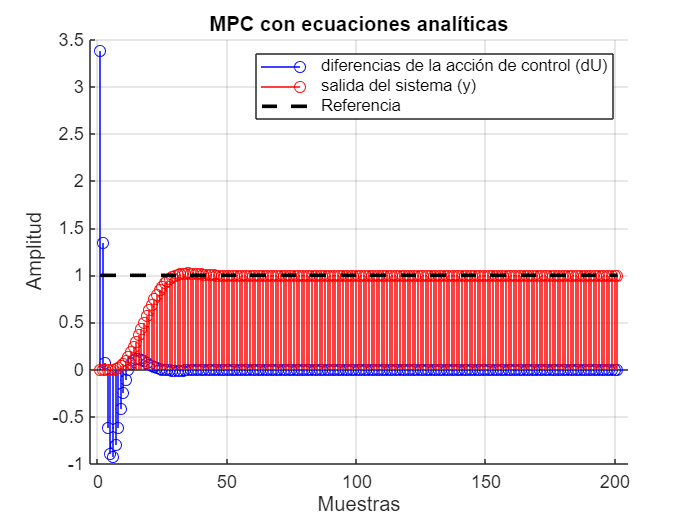


fig = figure();
hold on; grid on;
ylabel('Amplitud');
% ylabel('Tensión [Volts]');
xlabel('Muestras');

stem(x, 'b');
stem(y, 'r');
plot(ones(1, length(y)), '--k', 'LineWidth', 2);

title('MPC con ecuaciones analíticas');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');

Ahora si quiero aplicar restricciones a la acción de control por ejemplo, no podría resolverlo de manera analítica, necesitaria usar un solver, por ejemplo empleo uno de la librería yamilp:

nx = length(A_expanded);                     
nu = 1;                      
ny = 1;                      

R = rw * eye(nu);

% YALMIP
u = sdpvar(Nc, nu);
x = sdpvar(nx, Np+1);
r = sdpvar(Np, ny);

constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k) + B_expanded*u(k)];
    constraints = [constraints, -5 <= u(k) <= 5];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1)) + u(k)' * R * u(k);
end

% Condiciones y coste
for k = Nc+1:Np
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k)];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1));
end

ops = sdpsettings('verbose', 2);
controller = optimizer(constraints, objective, ops, {x(:,1), r(:)}, u(:));

% simulacion
state = zeros(nx, 1);             
r_sim = ones(Np, ny);          
sim_steps = 201;                
du = zeros(Nc, sim_steps); 
ys = zeros(sim_steps, 1);   

for k = 1:sim_steps
    [u_opt, diagnostics] = controller({state, r_sim});
    
    if diagnostics == 1
        error('Error con el controller/solver');
    end
    
    u_k = u_opt(1);
    du(1, k) = u_k;
    
    state = A_expanded*state + B_expanded*u_k;
    y_k = C_expanded*state;
    ys(k) = y_k;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

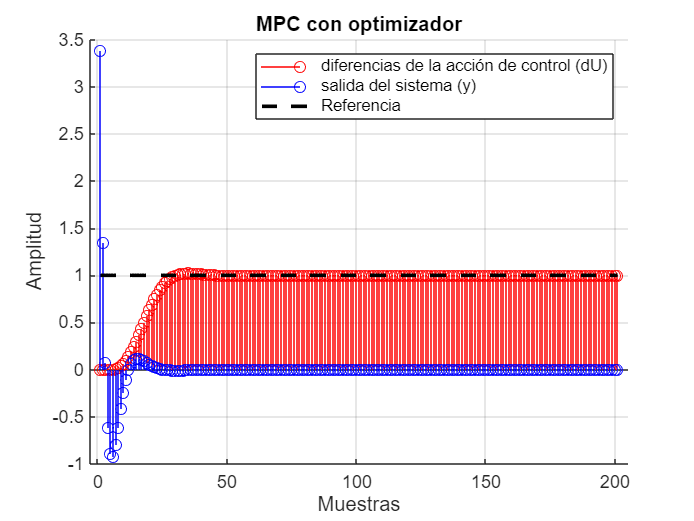


figure; hold on; grid on;
stem(ys, 'r');
stem(du(1, :), 'b');
plot(ones(1, length(ys)), '--k', 'LineWidth', 2);

title('MPC con optimizador');
ylabel('Amplitud');
xlabel('Muestras');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');

Ahora vuelvo a calcular lo mismo que antes pero aplicando las restricciones a la de accion de control (**NO** a la $\left.\Delta U\right)$

Era todo el objetivo de lo anterior, pero lo de antes es a modo de demostración que se llega a la misma resolución que de manera analítica

% numG = [10];
% denG = [1 0.1 3];
% [Ac, Bc, Cc, Dc] = tf2ss(numG, denG);
% plantac = ss(Ac, Bc, Cc, Dc);
% ts = 0.01;
% plantad = c2d(plantac, ts);
% Am = plantad.A;
% Bm = plantad.B;
% Cm = plantad.C;
% Dm = plantad.D;
% A = [Am [0 0]'; Cm * Am 1];
% B = [Bm; Cm * Bm];
% C = [[0 0] 1];
% D = 0;


% fopdt_delay = 0.33791;
% fopdt_time_constant = 0.28802;
% fopdt_gain = 1;
% fopdt_estimated = fopdt_gain/(s*fopdt_time_constant+1);
% fopdt_estimated.inputDelay = fopdt_delay;
% 
% fopdt_estimated = 1/(( (10e3)*(10e-6)*s + 1 )^6)
% 
% [p, z] = pzmap(fopdt_estimated);
% high_freq_pole = abs(max(p));
% 
% Ts = round(1/(5*high_freq_pole), 3)
% 
% model_discrete = c2d(fopdt_estimated, Ts)
% [model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});
% 
A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7
   x1    4.912   -10.05    10.98    -6.74    2.207  -0.3012        1
   x2        1        0        0        0        0        0        0
   x3        0        1        0        0        0        0        0
   x4        0        0        1        0        0        0        0
   x5        0        0        0        1        0        0        0
   x6        0        0        0        0        1        0        0
   x7        0        0        0        0        0        0        1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  7.491e-08    3.6e-06  1.608e-05  1.354e-05  2.152e-06  3.179e-08          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.


Am = model_A;
Bm = model_B;
Cm = model_C;
Dm = model_D;
A = A_expanded;
B = B_expanded;
C = C_expanded;
D = 0;

rest_u_inf = -100;
rest_u_sup = 100;

nx = length(A);
nu = 1;
ny = 1;

% Datos MPC
Np = 20;
Nc = 3;
rw = 1;
R = rw .* eye(nu);

% Variables
u = sdpvar(Nc, nu);
uant = sdpvar(1, 1);
x = sdpvar(nx, Np + 1);
r = sdpvar(Np, ny);

% Inicialización
constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:, k + 1) == A * x(:, k) + B * u(k)];
    constraints = [constraints, rest_u_inf <= uant + sum(u(1:k)) <= rest_u_sup];
    objective = objective + (r(k) - C * x(:, k + 1))' * (r(k) - C * x(:, k + 1)) + u(k)' * R * u(k);
end

for k = Nc + 1:Np
    constraints = [constraints, x(:, k + 1) == A * x(:, k)];
    objective = objective + (r(k) - C * x(:, k + 1))' * (r(k) - C * x(:, k + 1));
end

ops = sdpsettings('verbose', 2);
controller = optimizer(constraints, objective, ops, {x(:, 1), uant, r(:)}, u(:));

% Inicialización y parámetros
xm = zeros(nx-1, 1);
ym = Cm * xm;
u = 0;
dui = 0;
sim_i = 1;
sim_f = 1001;
xf = zeros(nx, 1);
reference = 1;
ref = reference*[ones(Np, 1)];
ua = 0;

deltaUs = zeros(sim_f, Nc);
dui = zeros(sim_f, 1);
us = zeros(sim_f, 1);
ys = zeros(sim_f, 1);
xs = zeros(length(xm), sim_f);

for ii = sim_i:sim_f
    deltaU = controller(xf, u, ref);
    deltaUs(ii, :) = deltaU;
    dua = deltaU(1);
    dui(ii) = dua;
    u = u + dua;
    ua = u;

    if (ua > rest_u_sup)
        ua = rest_u_sup;
    end
    if (ua < rest_u_inf)
        ua = rest_u_inf;
    end

    us(ii) = ua;
    ys(ii) = ym;
    xs(:, ii) = xm;
    xant = xm;
    xm = Am * xm + Bm * ua;
    ym = Cm * xm;
    xf = [xm - xant; ym];
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

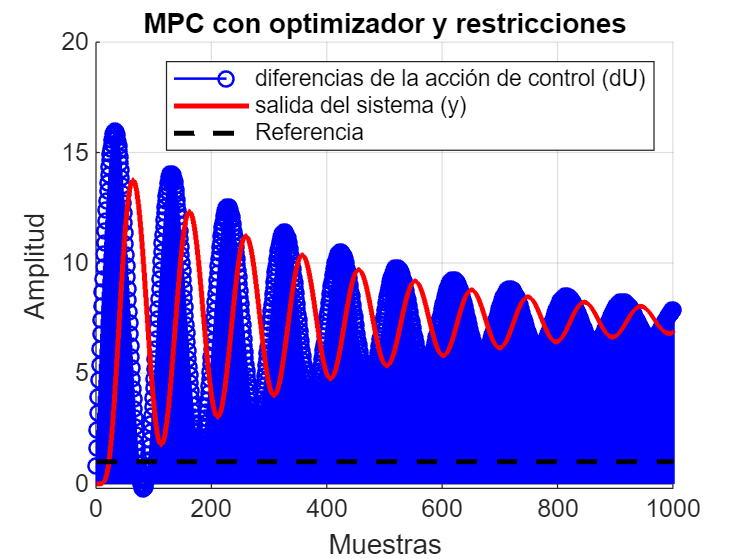


figure; hold on; grid on;
stem(us, 'b', 'LineWidth', 1);
stairs(ys, 'r', 'LineWidth', 2);
plot(reference*ones(1, length(ys)), '--k', 'LineWidth', 2);
xlim([0 sim_f]);

title('MPC con optimizador y restricciones');
ylabel('Amplitud');
xlabel('Muestras');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');